
param = getparam('L11-5v');

param = struct with fields:
    fc: 3


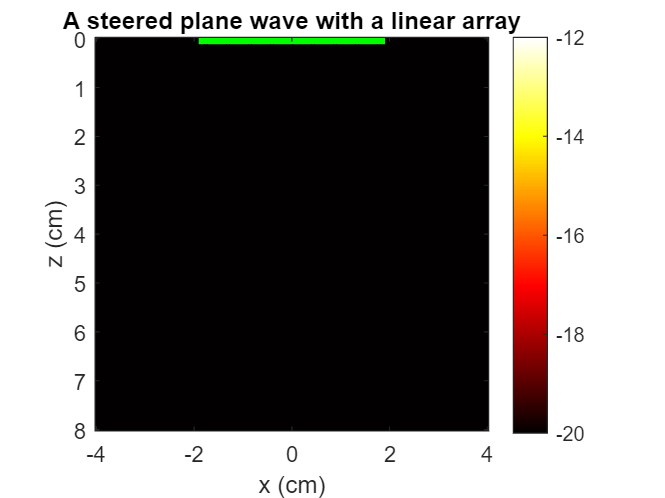



tilt = 10/180*pi; % tilt angle in rad
txdel = txdelay(param,tilt); % in s
x = linspace(-4e-2,4e-2,150); % in m
z = linspace(0,8e-2,150); % in m
[x,z] = meshgrid(x,z);
P = pfield(x,z,txdel,param);
imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
caxis([-20 0]) % dynamic range = [-20,0] dB
c = colorbar;
c.YTickLabel{end} = '0 dB';
colormap hot
axis equal ij tight
xlabel('x (cm)'), ylabel('z (cm)')
title('A steered plane wave with a linear array')

% Calculate the positions of the element centers.
L = param.pitch*(param.Nelements-1); % array aperture (in m)
xe = linspace(-0.5,0.5,param.Nelements)*L;
ze = zeros(1,param.Nelements);
hold on
plot(xe*1e2,ze*1e2,'g','Linewidth',5)
hold off

param = struct with fields:
           fc: 600000
         kerf: 3.0000e-05
        width: 2.7000e-04
        pitch: 3.0000e-04
    Nelements: 128
    bandwidth: 77
       radius: Inf
       height: 0.0050
        focus: 0.0180


param = struct with fields:
             fc: 1600000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.5000


param = struct with fields:
             fc: 2600000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.5000


param = struct with fields:
             fc: 3600000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.5000


param = struct with fields:
             fc: 4600000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.5000


param = struct with fields:
             fc: 5600000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.5000


param = struct with fields:
             fc: 6600000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.5000


param = struct with fields:
             fc: 7600000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.5000


param = struct with fields:
             fc: 8600000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.5000


param = struct with fields:
             fc: 9600000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.5000


param = struct with fields:
             fc: 10600000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.5000


param = struct with fields:
             fc: 11600000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.5000


param = struct with fields:
             fc: 12600000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.5000


param = struct with fields:
             fc: 13600000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.5000


param = struct with fields:
             fc: 14600000
           kerf: 3.0000e-05
          width: 2.7000e-04
          pitch: 3.0000e-04
      Nelements: 128
      bandwidth: 77
         radius: Inf
         height: 0.0050
          focus: 0.0180
    attenuation: 0.5000


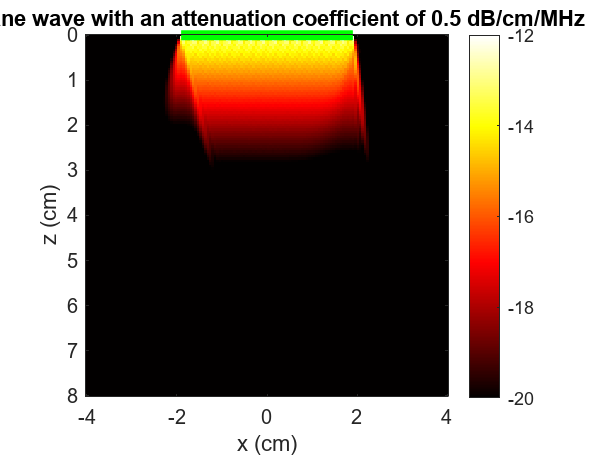


for fc = 0.6e6:1e6:14.6e6
    param = setfield(param,'fc',fc)
    
    param.attenuation = 0.5; % attenuation coefficient (in dB/cm/MHz)

    P = pfield(x,z,txdel,param);
    
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
    caxis([-20 0]) % dynamic range = [-20,0] dB
    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    colormap hot
    axis equal ij tight
    xlabel('x (cm)'), ylabel('z (cm)')
    title('A plane wave with an attenuation coefficient of 0.5 dB/cm/MHz')
    
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    hold off

    saveas(gcf,['change frequency' num2str(fc) '.jpg'])
end 